%% Task 1
% Compare the images and characterize the rails within each of the images

%% Task 1
%% --- 1.1 Define Dataset Path ---
% Set the path to your dataset folder (update this to your actual path)
datasetPath = './Data/Dataset - B2/';  % <-- update this

% Load all image files (common formats)
imgExtensions = {'*.jpg', '*.jpeg', '*.png', '*.bmp', '*.tif'};
imgFiles = [];
for k = 1:length(imgExtensions)
    found = dir(fullfile(datasetPath, imgExtensions{k}));
    imgFiles = [imgFiles; found]; %#ok<AGROW>
end

numImages = length(imgFiles);
fprintf('Total images found: %d\n', numImages);

Total images found: 15


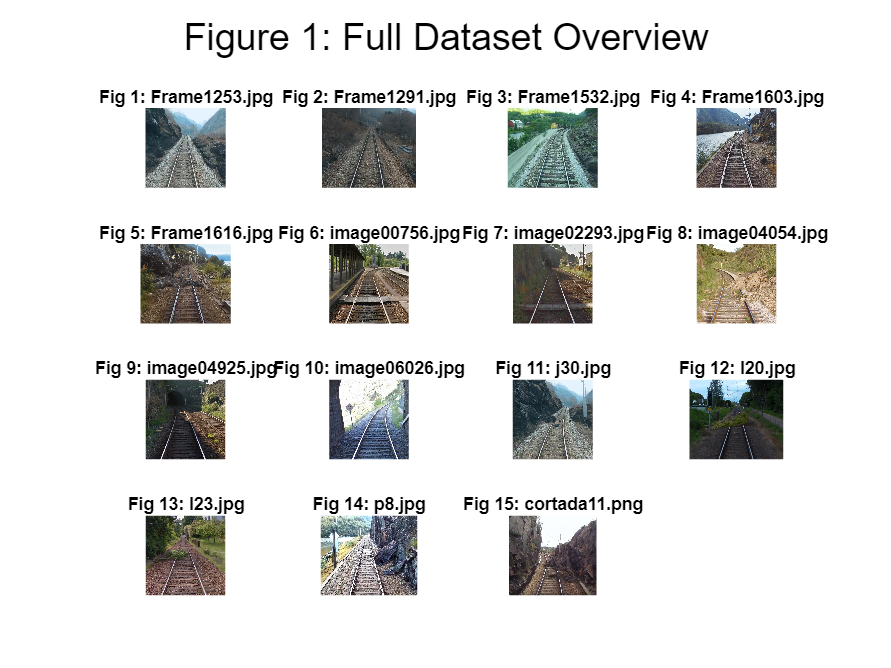


%% --- 1.2 Display All Images in a Grid ---
% Visual overview of the full dataset
cols = 4;
rows = ceil(numImages / cols);

figure('Name', 'Dataset Overview', 'NumberTitle', 'off');
for i = 1:numImages
    imgPath = fullfile(imgFiles(i).folder, imgFiles(i).name);
    img = imread(imgPath);
    subplot(rows, cols, i);
    imshow(img);
    title(sprintf('Fig %d: %s', i, imgFiles(i).name), ...
        'Interpreter', 'none', 'FontSize', 7);
end
sgtitle('Figure 1: Full Dataset Overview');